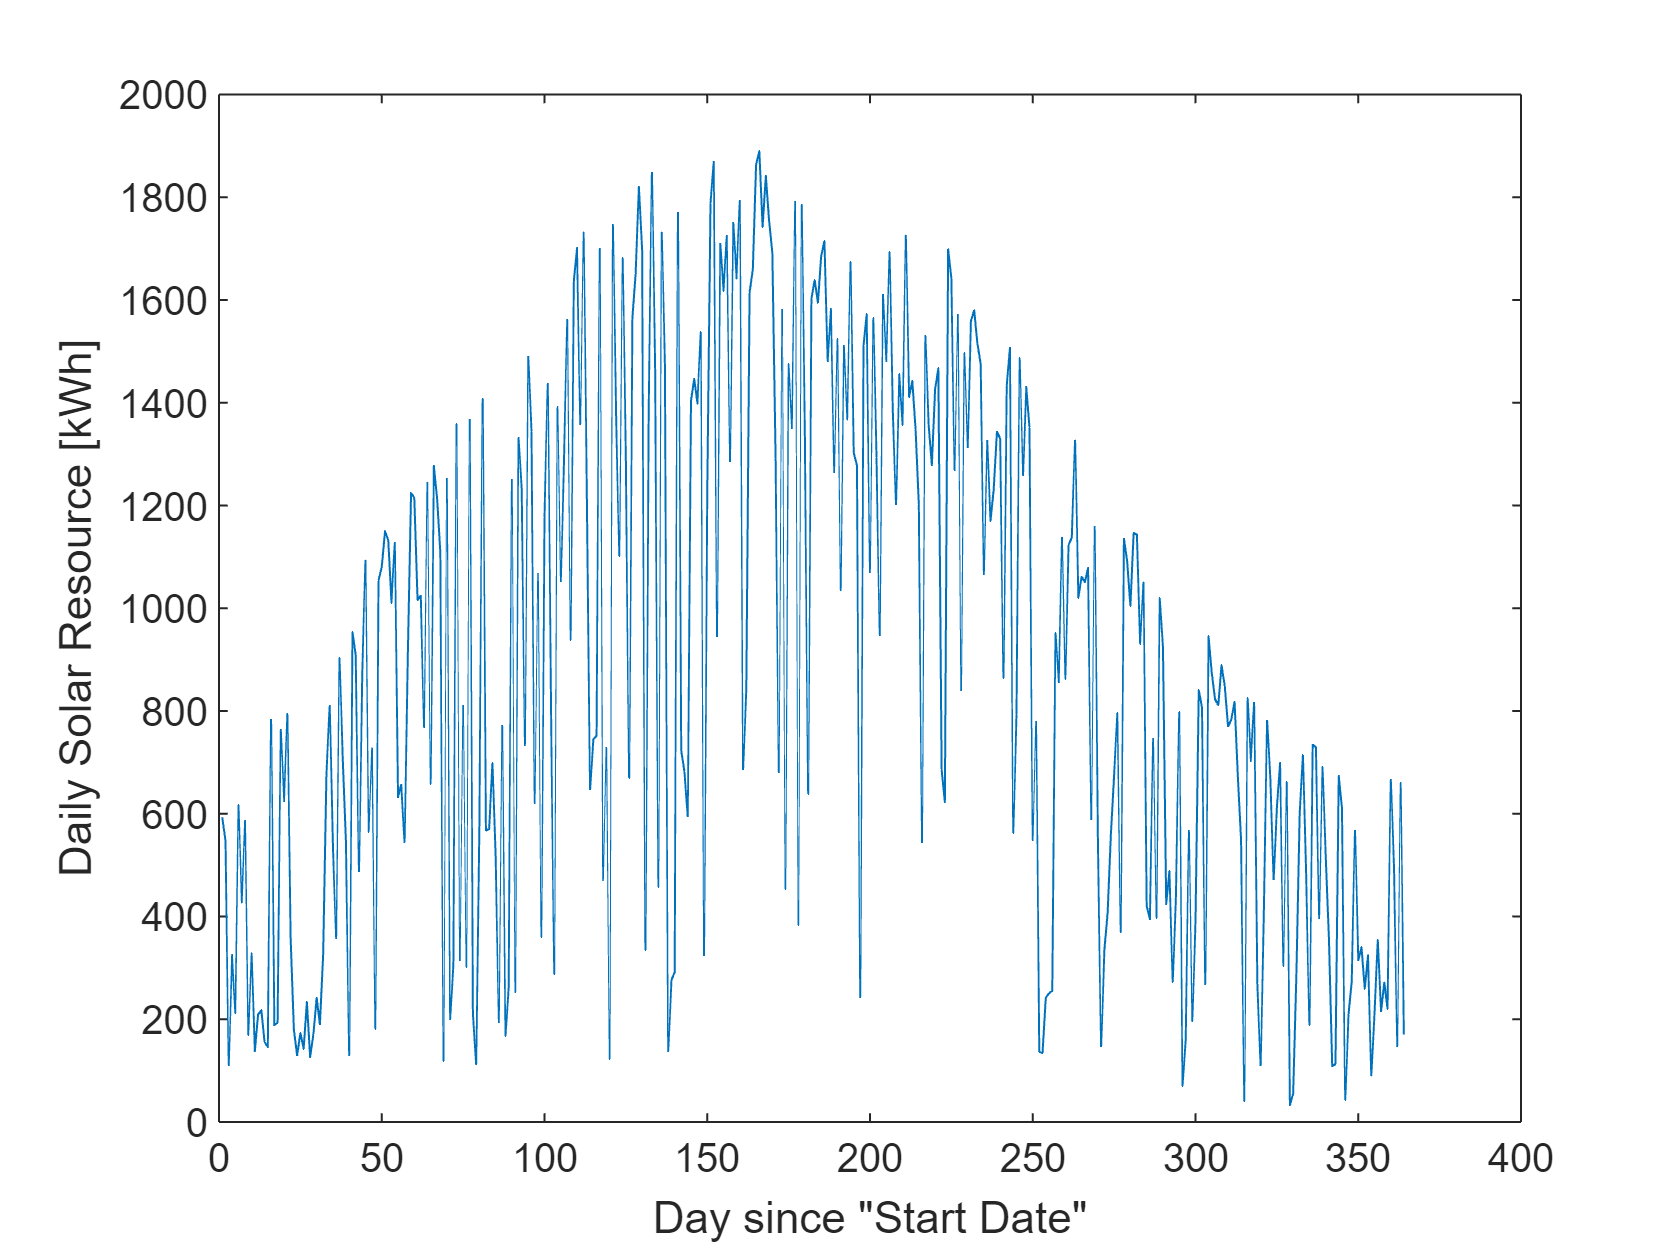


The total solar resource detected in Madison, WI by the ERB Solar Irradiance Detector from 01-01-20 to 12-29-20 is 321755.04 kWh.



% The Campus Solar Report
% Developed by Helios UW Madison
clc
clear 

% Run Function over a range of days
% Inputs: Start Date, number of days, beta, gamma, rho_g, array area)
dailyEnergy = loopCampusSolarTestFunction('01-01-20',364,10,0,0,214.3);   % 214.3m^2 is gordons area (pre-addition)

% Run Function for 1 day
% Inputs: Date, beta, gamma, rho_g, array area)
% CampusSolarTestFunction('07-05-21',10,0,0,214.3)   % 214.3m^2 is gordons area (pre-addition)

function [returnNum, count] = CampusSolarTestFunction(date_used, beta, gamma, rho_g, arrayarea)

% Basic inputs: 
lat_deg = 43.0725; % ERB Longitude
long_deg = -89.41133; % ERB Latitude
startdayofyear = day(datetime(date_used, 'InputFormat','MM-dd-yy'), 'dayofyear');
enddayofyear = startdayofyear+1;
start_Matrix_file_number = num2str((str2num(date_used(7:end))*1000)+startdayofyear);
end_Matrix_file_number = num2str((str2num(date_used(7:end))*1000)+enddayofyear);

%Downloading solar data directly form NOAA database
% filename=['msn' start_Matrix_file_number '.dat'];
% filename2=['msn' end_Matrix_file_number '.dat'];
% if isfile(filename)
%     %fprintf('already have the file |%s|\n',filename);
% else
%     url=['https://gml.noaa.gov/aftp/data/radiation/solrad/msn/20' start_Matrix_file_number(1:2) '/' filename];
%     outname=websave(filename,url);
%     B=readmatrix(filename);
% end
% if isfile(filename2)
%     %fprintf('already have the file |%s|\n',filename2)
% else
%     url2=['https://gml.noaa.gov/aftp/data/radiation/solrad/msn/20' end_Matrix_file_number(1:2) '/' filename2];
%     outname2=websave(filename2,url);
%     B2=readmatrix(filename2);
% end

% Define Madison_Data matrices from NOAA data
Mat1 = readmatrix(['msn' start_Matrix_file_number '.dat']);
Mat2 = readmatrix(['msn' end_Matrix_file_number '.dat']);
Madison_Data = [Mat1(362:end,[7 8 9 11 13]); Mat2(2:361,[7 8 9 11 13])];
decimaltime = Madison_Data(:,1)-6; %decimal time (hr) in CST (shifted by 6 hours from GMT) 
    %column 7 of NOAA
zenith = Madison_Data(:,2); %Zenith angle (degrees) 
    %column 8 of NOAA
dw_psp = Madison_Data(:, 3); %Total solar radiation (W/m^2)
    %column 9 of NOAA
direct = Madison_Data(:,4); %Direct solar radiation (W/m^2)  
    %column 11 of NOAA
diffuse = Madison_Data(:,5); %Diffuse solar radiation (W/m^2) 
    %column 13 of NOAA

% Troubleshooting purposes only!!! Finding how many error minutes there are
n = Mat1(2,2); %nth day of the year
count = 0;
for i=1:length(dw_psp)
    if((dw_psp(i) <= -5000 & diffuse(i) <= -5000) | (dw_psp(i) <= -5000 & direct(i) <= -5000) | (direct(i) <= -5000 & diffuse(i) <= -5000)) 
        count = count + 1;
    end
end

% Solving for lost direct solar data (when direct = -9999.9)
for i=1:length(dw_psp)
    if dw_psp(i) < 0 & direct(i) <= -9000
        direct(i) = 0; end
    if direct(i) <= -9000
        direct(i) = (dw_psp(i) - diffuse(i))/cosd(zenith(i)); end
end

% Replaces all negative radiation values with 0
direct = max(direct,0); 
dw_psp = max(dw_psp,0); 
diffuse = max(diffuse,0); 

% Replace all zenith angles over 90 to 0 (avoid 90 because of divide by 0 error in Rb equation) to prevent a negative Rb
for i=1:length(decimaltime)      
    if zenith(i)>=90 
        zenith(i) = 0; end
    if decimaltime(i) < 0
        decimaltime(i) = decimaltime(i) + 24; end
end

%Solar Time Conversion
delta = 23.45*sind(360*((284+n)/365));
L_st = 90; %deg
L_loc = 89.4; %deg
B = ((n-1)*360)/365; %deg
E = 229.2*(0.000075 + 0.001868*cosd(B) - 0.032077*sind(B) - 0.014615*cosd(2*B) - 0.04089*sind(2*B)); %E is in minutes
t_Solar_min = decimaltime.*60 + 4*(L_st - L_loc) + E;   % since E is in minutes, decimal time must be in minutes
t_Solar_hr = t_Solar_min./60; 
omega = t_Solar_hr.*15 - 180; 
inc_angle = acosd((sind(delta).*sind(lat_deg).*cosd(beta))-(sind(delta).*cosd(lat_deg).*sind(beta).*cosd(gamma))+(cosd(delta).*cosd(lat_deg).*cosd(beta).*cosd(omega))+(cosd(delta).*sind(lat_deg).*sind(beta).*cosd(gamma).*cosd(omega))+(cosd(delta).*sind(beta).*sind(gamma).*sind(omega)));
for i=1:length(inc_angle) %Replaces angles greater than 90 with 90 to prevent a negative Rb
    if inc_angle(i) >= 90    
        inc_angle(i) = 89.999;
    end
end

% Calculation of Daily Solar Energy
Rb = cosd(inc_angle)./cosd(zenith);
direct_hz = direct.*cosd(zenith);
MinutePower = direct_hz.*Rb + diffuse.*((1+cosd(beta))/2) + rho_g.*(direct_hz+diffuse).*(1-cosd(beta))/2 ; % Irradiance in W/m^2 for each minute
MinuteEnergy = MinutePower*(1/60); % Multiply by 1/60th of an hour (one minute)
TotalDailyEnergy = sum(MinuteEnergy)*arrayarea; % in Wh
returnNum = TotalDailyEnergy/1000;
%fprintf('\nThe daily solar radiation detected in Madison, WI by the ERB Solar Irradiance Detector on %s is %.2f kWh.\n', date, returnNum); %Insert correct date, " on a solar panel with x slope"**
%fprintf('\nWith an assumed efficiency of 0.15756 applied: %.2f kWh.\n\n',(returnNum*0.15756));
end




% Function definition to run 'CampusSolarTestFunction' for n days (n = numdays)
function dailyEnergy = loopCampusSolarTestFunction(start_date, numdays, beta, gamma, rho_g, arrayarea)
dt = datetime(start_date,'InputFormat','MM-dd-yy');
jd = juliandate(dt);
TotalRad = 0;
count = 0;

% Loop through all days in range
for i=1:numdays
    dateStart = char(datetime(jd,'convertfrom','juliandate','Format','MM-dd-yy'));
    dateEnd =  char(datetime(jd+1,'convertfrom','juliandate','Format','MM-dd-yy'));
    [dailykWh, countOut] = CampusSolarTestFunction(dateStart, beta, gamma, rho_g, arrayarea);
    TotalRad = TotalRad + dailykWh;
    jd = jd+1;
    count = count + countOut;
    dailyEnergy(i) = dailykWh;
end

last_date = dateStart;
plot(dailyEnergy)
xlabel('Day since "Start Date"')
ylabel('Daily Solar Resource [kWh]')
fprintf('\nThe total solar resource detected in Madison, WI by the ERB Solar Irradiance Detector from %s to %s is %.2f kWh.\n\n', start_date, last_date, TotalRad)
end


